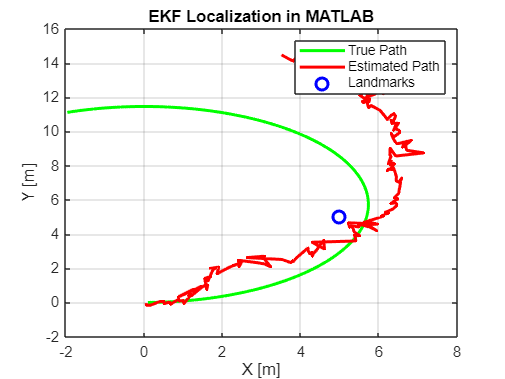

clear; clc; close all;

% Initial state
x_true = [0; 0; 0];       % Actual robot position
x_est = [0; 0; 0];        % EKF estimate
P = eye(3);               % Initial covariance

% Noise
Q = diag([0.5, 0.5, deg2rad(3)].^2);%Motion Noise
R = 0.2^2;               % Measurement noise variance (range only)


% Landmarks [x y] (multiple)
landmark = [5, 5];

% Time setup
dt = 0.1;
T = 20;
steps = T / dt;

% Logs
x_log = zeros(3, steps);      % True positions
x_est_log = zeros(3, steps);  % Estimated positions

for i = 1:steps
    % Control input: linear velocity and angular velocity
    u = [1; deg2rad(10)];%for circular motion

    % %sqaure motion
    % side_time = 2;            % time to move straight for one side
    % omega = deg2rad(45);      % rotation speed
    % turn_time = pi/2 / omega; % time to rotate 90 degrees
    % v = 1;                    % forward speed
    % 
    % t = i * dt;
    % 
    % % Determine which phase we're in
    % cycle_time = side_time + turn_time;
    % phase_time = mod(t, cycle_time);
    % 
    % if phase_time < side_time
    %     u = [v; 0];  % move straight
    % else
    %     u = [0; omega];  % rotate
    % end
    % Simulate true motion
    x_true = motion_model(x_true, u, dt);

    % ---------- EKF Prediction Step ----------
    [x_pred, F] = motion_model(x_est, u, dt);  % Predicted next state
    P = F * P * F' + Q;                        % Predicted covariance

    % ---------- EKF Update Step for All Landmarks ----------
    for j = 1:size(landmark, 1)
        % only for range 
        % Simulated noisy range measurement from current landmark
        dx = landmark(j,1) - x_true(1);
        dy = landmark(j,2) - x_true(2);
        range = sqrt(dx^2 + dy^2) + randn * sqrt(R);

        % Measurement model (expected range + Jacobian)
        [z_pred, H] = measurement_model(x_pred, landmark(j,:));
        z = range;
        y = z - z_pred;              % Innovation
        S = H * P * H' + R;          % Innovation covariance
        K = P * H' / S;              % Kalman gain

        % Update state estimate and covariance
        x_pred = x_pred + K * y;
        P = (eye(3) - K * H) * P;
    end

    % Save updated state
    x_est = x_pred;

    % Log
    x_log(:, i) = x_true;
    x_est_log(:, i) = x_est;
end

% ---------- Plot ----------
figure;
plot(x_log(1, :), x_log(2, :), 'g', 'LineWidth', 2); hold on;
plot(x_est_log(1, :), x_est_log(2, :), 'r', 'LineWidth', 2);
plot(landmark(:,1), landmark(:,2), 'bo', 'MarkerSize', 8, 'LineWidth', 2);
legend('True Path', 'Estimated Path', 'Landmarks');
title('EKF Localization in MATLAB');
xlabel('X [m]'); ylabel('Y [m]'); grid on;